Dylan Thornburg ECEN 133 Prelab 6: 

• Read the Laboratory 6 Hardware Set-Up Document. 

• For the 8 low order filters listed below, use MATLAB to plot the linear magnitude frequency response and to plot the log magnitude frequency response in dB. For each filter: 

        o Identify the frequency ranges where the amplitude is reduced by more than 20 dB. 

        o Identify the frequency ranges where the amplitude is reduced by more than 40 dB. 

        o Find the amplitude expected for 6 octaves of C-notes on a piano. The highest note we will hear is C8 at a frequency of 4186.01Hz. To lower any note an octave, it’s frequency should be divided by 2. 

           The note an octave lower, C7, will have a frequency that is half the frequency of C8. Compute the six frequencies of all the C notes from C3 (low C) to C8, and for each compute the expected output amplitude for the filter.

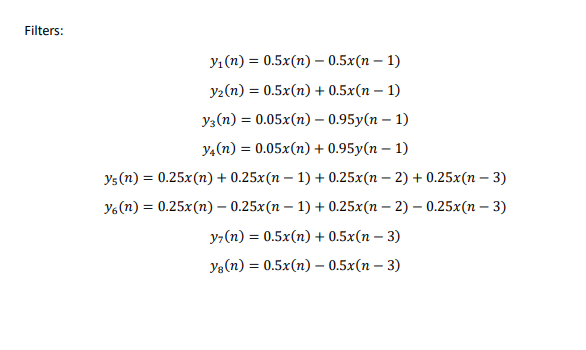

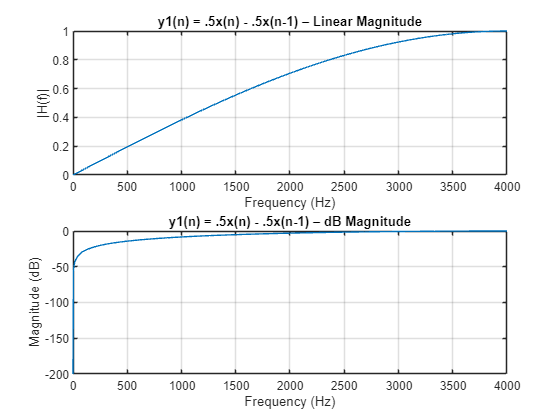

y1(n) = .5x(n) - .5x(n-1) attenuates >20dB from 0.0 Hz to 254.2 Hz


y1(n) = .5x(n) - .5x(n-1) attenuates >40dB from 0.0 Hz to 23.5 Hz


C-note amplitudes:


    C8: 1.0000
    C7: 0.7316
    C6: 0.3996
    C5: 0.2041
    C4: 0.1026
    C3: 0.0506


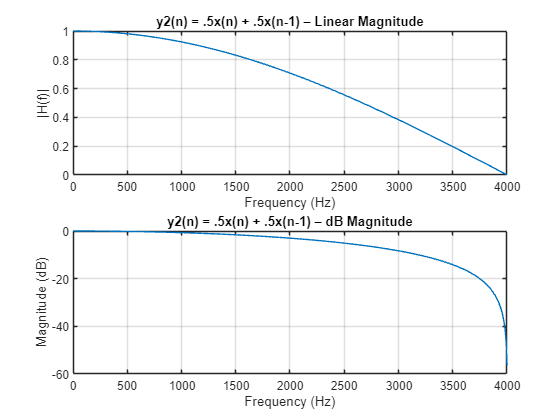

y2(n) = .5x(n) + .5x(n-1) attenuates >20dB from 3749.8 Hz to 4000.0 Hz


y2(n) = .5x(n) + .5x(n-1) attenuates >40dB from 3980.4 Hz to 4000.0 Hz


C-note amplitudes:


    C8: 0.0015
    C7: 0.6817
    C6: 0.9167
    C5: 0.9789
    C4: 0.9947
    C3: 0.9987


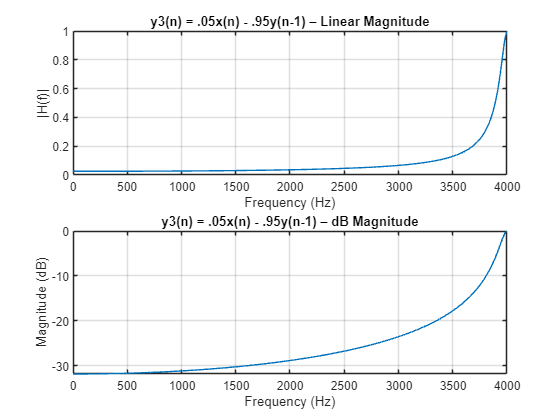

y3(n) = .05x(n) - .95y(n-1) attenuates >20dB from 0.0 Hz to 3343.1 Hz


C-note amplitudes:


    C8: 0.9982
    C7: 0.0376
    C6: 0.0280
    C5: 0.0262
    C4: 0.0258
    C3: 0.0257


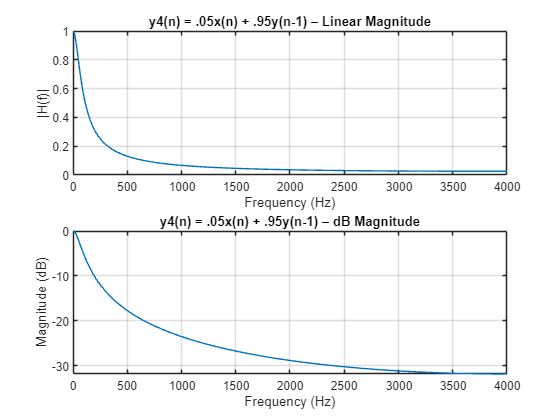

y4(n) = .05x(n) + .95y(n-1) attenuates >20dB from 660.8 Hz to 4000.0 Hz


C-note amplitudes:


    C8: 0.0256
    C7: 0.0350
    C6: 0.0641
    C5: 0.1247
    C4: 0.2425
    C3: 0.4521


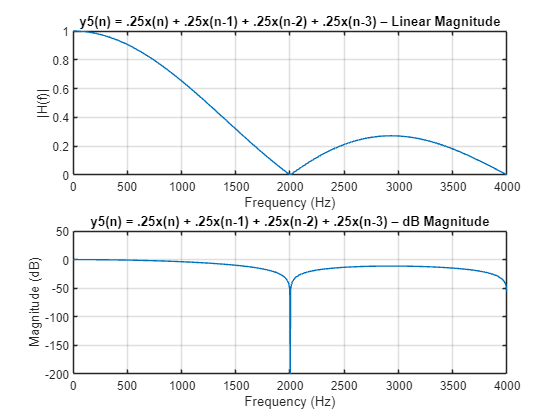

y5(n) = .25x(n) + .25x(n-1) + .25x(n-2) + .25x(n-3) attenuates >20dB from 1833.8 Hz to 4000.0 Hz


y5(n) = .25x(n) + .25x(n-1) + .25x(n-2) + .25x(n-3) attenuates >40dB from 1986.3 Hz to 4000.0 Hz


C-note amplitudes:


    C8: 0.0015
    C7: 0.0481
    C6: 0.6239
    C5: 0.8974
    C4: 0.9738
    C3: 0.9936


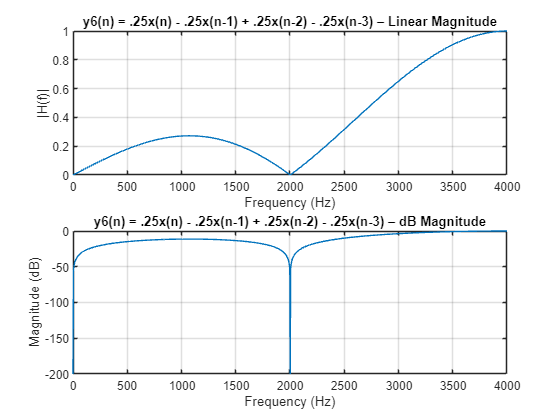

y6(n) = .25x(n) - .25x(n-1) + .25x(n-2) - .25x(n-3) attenuates >20dB from 0.0 Hz to 2170.1 Hz


y6(n) = .25x(n) - .25x(n-1) + .25x(n-2) - .25x(n-3) attenuates >40dB from 0.0 Hz to 2017.6 Hz


C-note amplitudes:


    C8: 1.0000
    C7: 0.0516
    C6: 0.2720
    C5: 0.1871
    C4: 0.1004
    C3: 0.0503


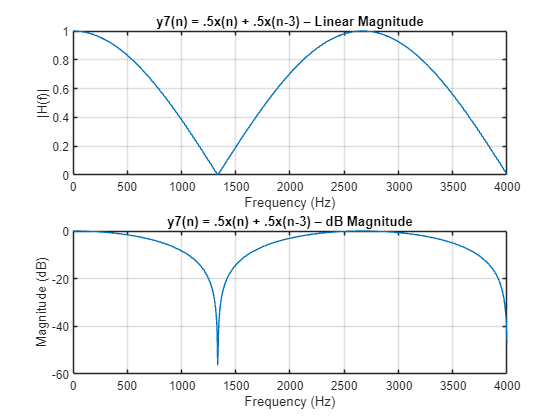

y7(n) = .5x(n) + .5x(n-3) attenuates >20dB from 1251.2 Hz to 4000.0 Hz


y7(n) = .5x(n) + .5x(n-3) attenuates >40dB from 1329.4 Hz to 4000.0 Hz


C-note amplitudes:


    C8: 0.0046
    C7: 0.7779
    C6: 0.3311
    C5: 0.8158
    C4: 0.9528
    C3: 0.9885


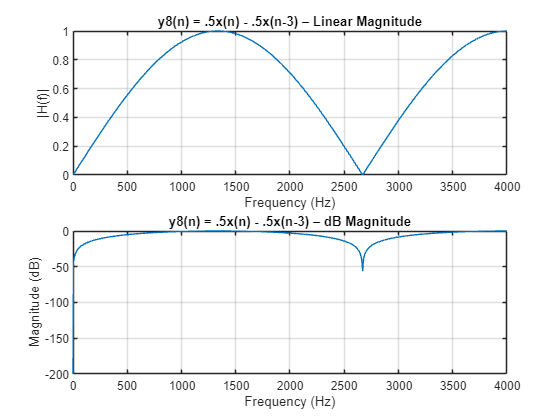

y8(n) = .5x(n) - .5x(n-3) attenuates >20dB from 0.0 Hz to 2752.7 Hz


y8(n) = .5x(n) - .5x(n-3) attenuates >40dB from 0.0 Hz to 2674.5 Hz


C-note amplitudes:


    C8: 1.0000
    C7: 0.6284
    C6: 0.9436
    C5: 0.5783
    C4: 0.3035
    C3: 0.1513


Fs = 8000;                        
f = linspace(0, Fs/2, 1024);      

% C8 to C3
C_freqs = [4186.01, 2093, 1046.5, 523.25, 261.63, 130.81];
C_labels = {'C8','C7','C6','C5','C4','C3'};


% y1(n) = .5x(n) - .5x(n-1)
b1 = [.5, -.5]; 
a1 = 1;

% y2(n) = .5x(n) + .5x(n-1)
b2 = [.5, .5]; 
a2 = 1;

% y3(n) = .05x(n) - .95y(n-1)
b3 = .05; 
a3 = [1, .95];

% y4(n) = 0.05x(n) + 0.95y(n-1)
b4 = .05; 
a4 = [1, -.95];

% y5(n) = .25x(n) + .25x(n-1) + .25x(n-2) + .25x(n-3)
b5 = [.25, .25, .25, .25]; 
a5 = 1;

% y6(n) = .25x(n) - .25x(n-1) + .25x(n-2) - .25x(n-3)
b6 = [.25, -.25, .25, -.25]; 
a6 = 1;

% y7(n) = .5x(n) + .5x(n-3)
b7 = [.5, 0, 0, .5]; 
a7 = 1;

% y8(n) = .5x(n) - .5x(n-3)
b8 = [.5, 0, 0, -.5]; 
a8 = 1;

bs = {b1,b2,b3,b4,b5,b6,b7,b8};
as = {a1,a2,a3,a4,a5,a6,a7,a8};
labels = {
    'y1(n) = .5x(n) - .5x(n-1)', 
    'y2(n) = .5x(n) + .5x(n-1)',
    'y3(n) = .05x(n) - .95y(n-1)',
    'y4(n) = .05x(n) + .95y(n-1)',
    'y5(n) = .25x(n) + .25x(n-1) + .25x(n-2) + .25x(n-3)',
    'y6(n) = .25x(n) - .25x(n-1) + .25x(n-2) - .25x(n-3)',
    'y7(n) = .5x(n) + .5x(n-3)',
    'y8(n) = .5x(n) - .5x(n-3)'
};

for i = 1:length(bs)
    b = bs{i}; 
    a = as{i}; 
    desc = labels{i};

    [H, ~] = freqz(b, a, 1024);
    mag = abs(H);
    mag_dB = 20 * log10(mag + 1e-10);  % +1e-10 to avoid log(0)

    figure;
    subplot(2,1,1); plot(f, mag); grid on;
    title([desc ' – Linear Magnitude']);
    xlabel('Frequency (Hz)'); ylabel('|H(f)|');

    subplot(2,1,2); plot(f, mag_dB); grid on;
    title([desc ' – dB Magnitude']);
    xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');

    % Finds 20dB and 40dB attenuation ranges
    i20 = find(mag_dB < -20);
    i40 = find(mag_dB < -40);

    if ~isempty(i20)
        fprintf('%s attenuates >20dB from %.1f Hz to %.1f Hz\n', ...
            desc, f(i20(1)), f(i20(end)));
    end
    
    if ~isempty(i40)
        fprintf('%s attenuates >40dB from %.1f Hz to %.1f Hz\n', ...
            desc, f(i40(1)), f(i40(end)));
    end

    fprintf('C-note amplitudes:\n');
    for j = 1:length(C_freqs)
        [~, idx] = min(abs(f - C_freqs(j)));
        fprintf('    %s: %.4f\n', C_labels{j}, mag(idx));
    end
    fprintf('\n \n \n \n \n');
end